# Gauß-Newton als Fixpunktiteration

Wir betrachten das nichtlineare Ausgleichsproblem 

$\min_{x \in [0, 2 \pi)} \|F(x)\|_2, \quad F(x):=(a + r \cos x,r \sin x)^T$,

mit Parametern $a > r >0$, siehe Beispiel 6.4 im Buch. Die Gauß-Newton-Methode zur numerischen Lösung dieses Problems kann man äquivalent als Fixpunktiteration

         $x_{k+1} =\Phi(x_k), ~~ \Phi(x):=x+\frac{a}{r} \sin x
$,  $x \in [0,2 \pi )$

darstellen (siehe Buch).  Es gilt: $\Phi(x^\ast)=x^\ast$ für  $x^\ast=0$, $x^\ast = \pi$.

Wir  wählen den Parameterwert $q:=\frac{a}{r} \geq1$ und einen Startwert $x_0 \in (0,2 \pi)$:

x0=2.5;
global q;
q=1.8;

Es  werden 10 Fixpunktiterationen mit diesem Startwert berechnet und die Ergebnisse $x_k$, $k=0,\ldots, 10$, werden gezeigt. Der Verlauf der Fixpunktiteration wird geplottet.

# Aktivität:

Variieren Sie den Parameterwert $q \in [1,4]$. und den Startwert $x_0\in (0,2\pi)$ und untersuchen Sie die Konvergenz des Gauß-Newton-Verfahrens für dieses Beispielproblem. In welchem Sinne ist  $q=2$ ein kritischer Parameterwert?

%% Initialisierung
loop=11;
Erg=zeros(loop,1);
xn=x0;
Erg(1)=xn;
%% Iterationen 1 bis 10
for i=2:loop
    xn=phi(xn);
    Erg(i)=xn;
end
fprintf('\n Resultate x_k, k=0,1,..,10, der Fixpunktiteration: \n');


 Resultate x_k, k=0,1,..,10, der Fixpunktiteration: 


Erg

Erg =     2.5000
    3.5772
    2.8176
    3.3906
    2.9470
    3.2951
    3.0199
    3.2384
    3.0644
    3.2032


loop = 11

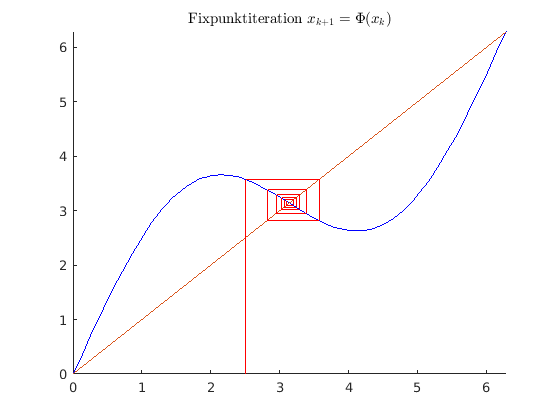

visualize(Erg)

function xnew=phi(x)
    global q;
    xnew = x +q*sin(x);
end

function visualize(Erg)
clf reset;
figure(1)
axis([ 0 6.3 0 6.3]);
hold on;
fplot(@(x) phi(x),[0 6.3],'b')
plot([0 6.3],[0 6.3]);
plot([Erg(1) Erg(1)],[0 phi(Erg(1))],'r');
title('Fixpunktiteration $x_{k+1}=\Phi(x_k)$','Interpreter','latex');
loop= size(Erg,1)
for i=1:loop-1
    plot([Erg(i+1) Erg(i+1)], [Erg(i+1) phi(Erg(i+1))],'r');
    plot([Erg(i+1) Erg(i)], [phi(Erg(i))  Erg(i+1)],'r');
end
end